# load image

%[fname, dname] = uigetfile('M:\Bergles Lab Data\Projects\In vivo imaging\*.tif','Multiselect','on');
[fname, dname] = uigetfile('M:\Bergles Lab Data\Papers\P2ry1\*.czi','Multiselect','on');

[~,~,ext] = fileparts([dname, fname]);

%%tif performance 
if strcmp(ext,'.tif') 
    tic;
    X = loadTif([dname fname],16);
    toc;
elseif strcmp(ext,'.czi')
    tic;
    X = bfLoadTif([dname fname]);
    X = imrotate(X,180);
    toc;
else
    disp('Invalid image format.')
end

Unknown IlluminationType value 'Fluorescence' will be stored as "Other"
Reading series #1
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ...........................................................

Elapsed time is 92.699931 seconds.


## get 10th percentiles

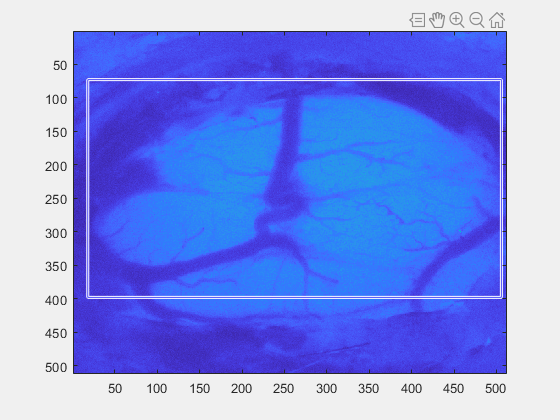

%cut down image first, then do normalization
figure; 
imagesc(X(:,:,1));
caxis([min(min(X(:,:,1))) max(max(X(:,:,1)))]);
recth = imrect(gca,[12 0 488 325]);
fcn = makeConstrainToRectFcn('imrect',get(gca,'XLim'),get(gca,'YLim'));
setPositionConstraintFcn(recth,fcn);
setResizable(recth,0);
wait(recth);

[s] = round(recth.getPosition); x = s(1); y = s(2); w=s(3), h=s(4);

w = 488

Y = zeros(h,w,size(X,3));
Y = X(y:y+h-1,x:x+w-1,:);

clear X;
tic;
[dFoF, Fo] = normalizeImg(Y, 10, 1); toc;

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 2047.837730 

Bleach correction finished. Subtracting baseline...
Elapsed time is 23.185285 seconds.


 %get Fo and display it

## Set ROI masks and generate signals

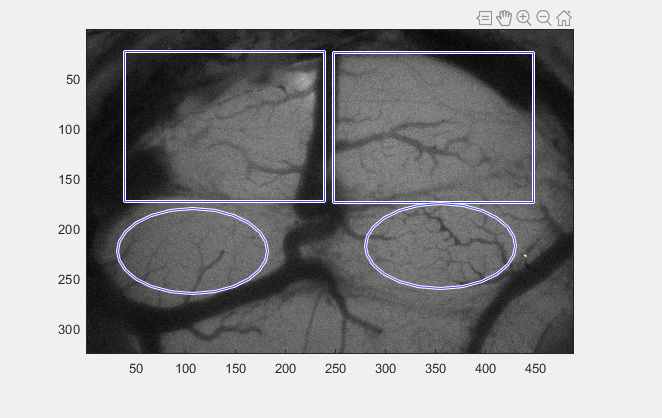

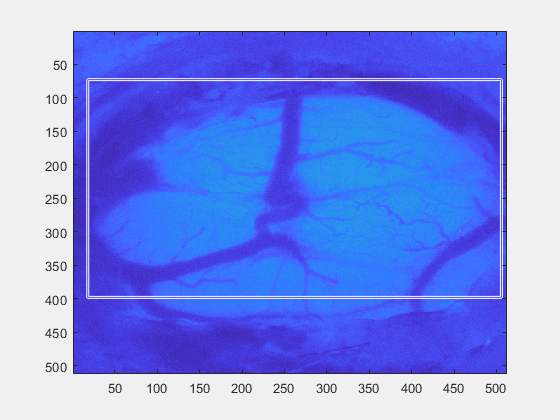

[LICmask, RICmask, LSCmask, RSCmask] = getIC_SCmasks(Y);

 LICsignal = getMeanFromMask(dFoF, LICmask);
 RICsignal = getMeanFromMask(dFoF, RICmask);
 ctxsignal = [getMeanFromMask(dFoF,LSCmask) + getMeanFromMask(dFoF,RSCmask)]/2;


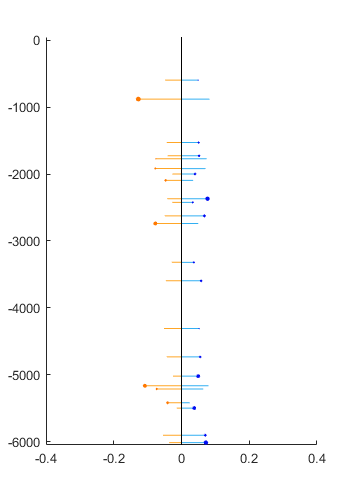

h1 =   Figure (52) with properties:

      Number: 52
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1.8000 1.2000]
       Units: 'inches'

  Show all properties


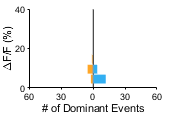

Rdom = 16

tempPkData = 	1.0e+03 *

    0.8790    0.0001    0.8790    0.0001    0.0000    0.0020    0.0010
    1.7710    0.0001    1.7710    0.0001    0.0000    0.0010    0.0010
    1.9160    0.0001    1.9170    0.0001    0.0000    0.0010    0.0010
    2.0930    0.0000    2.0940    0.0000    0.0000    0.0010    0.0010
    2.7380    0.0001    2.7380    0.0000    0.0000    0.0020    0.0010
    5.1650    0.0001    5.1650    0.0001    0.0000    0.0020    0.0010
    5.2120    0.0001    5.2130    0.0001    0.0000    0.0010    0.0010
    5.4190    0.0000    5.4190    0.0000    0.0000    0.0020    0.0010


LIC: 12 peaks total, 8 corresponding RIC peaks.
RIC: 20 peaks total, 8 corresponding LIC peaks.
Mean RIC amplitude: 0.056308
Mean LIC amplitude: 0.05171
M:\Projects and Analysis\Papers\P2ry1\Fig - In vivo bilateral ablations\Data\Experiment-662\Experiment-662\ICinfo16_dFoF


%make folders and analyzes IC activity
foldername = regexp(fname,'Experiment-\d*','match');
foldername = foldername{1};
mkdir(dname,foldername);

[stats, pkData] = P2ry1_findICpeaksdFoF(double([LICsignal RICsignal ctxsignal]),[dname foldername],'dFoF',1);

save([dname '\' foldername '\dFoFvars.mat'],'Fo');
%writeTif(single(mean(img-Fo,3)),[dname '\' foldername '\meantif.tif'],32);


%[SCactivity, bin, bin2] = getSCactivity(dFoF,LSCmask);
%[RSCactivity, Rbin, Rbin2] = getSCactivity(dFoF,RSCmask);
[SCactivity, bin, events] = getSCactivity_new(dFoF,LSCmask);

ans =      1   264


[RSCactivity, Rbin, Revents] = getSCactivity_new(dFoF,RSCmask);

ans =      1   114


stats = struct([]);
%%some stats
stats(1).baselineFreq = size(events([events.startFrame] < 3000),2) + size(Revents([Revents.startFrame] < 3000),2);
stats.baselineDur = mean([events([events.startFrame] < 3000).dur Revents([Revents.startFrame] < 3000).dur]);
LidxMRS = [[events.startFrame] < 9000 & [events.startFrame] > 6000];
RidxMRS =[[Revents.startFrame] < 9000 & [Revents.startFrame] > 6000];
stats.mrsFreq = size([events(LidxMRS)],2) + size([Revents(RidxMRS)],2);
stats.mrsDur = mean([events(LidxMRS).dur Revents(RidxMRS).dur]);
stats.Levents = events;
stats.Revents = Revents;
stats.Lbin = bin;
stats.Rbin = Rbin;
stats

stats = struct with fields:
    baselineFreq: 11
     baselineDur: 20.9182
         mrsFreq: 0
          mrsDur: NaN
         Levents: [1×9 struct]
         Revents: [1×12 struct]
            Lbin: [6048×1200 logical]
            Rbin: [6048×1200 logical]


savename = regexp(fname,'Experiment-\d*','match');
savename = savename{1};
save([dname savename '_stats.mat'],'stats','LICmask', 'RICmask','LSCmask', 'RSCmask','-v7.3');
% save([dname savename '_dFoF.mat'],'dFoF','-v7.3');

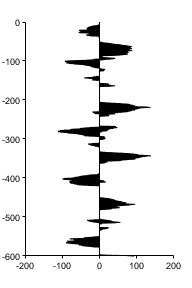

time = [1:1:size(bin,1)]/10;
figure; %plot(sum(-bin,2),-time); hold on; plot(sum(Rbin,2),-time);
l = getRealEvents(bin);
r = getRealEvents(Rbin);
area(-time,-l,'FaceColor','k'); hold on;
area(-time,r,'FaceColor','k');
xlim([-600 0]);
ylim([-200 200])
set(gca,'view',[90 -90])
figQuality(gcf,gca,[4 6]/2);

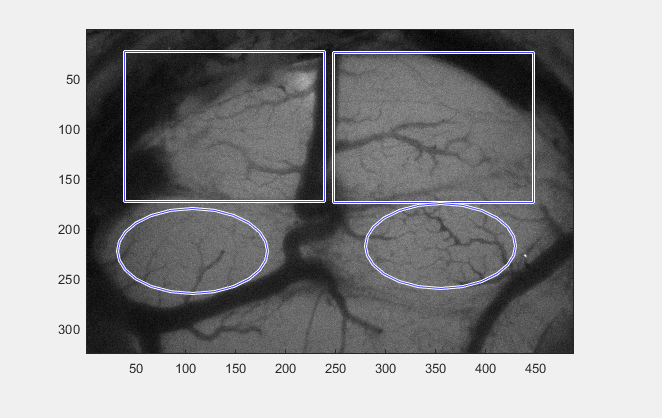

Error using export_fig>parse_args (line 1102)
Folder .\EPS Panels does not exist!

Error in export_fig (line 279)
    [fig, options] = parse_args(nargout, fig, varargin{:});

export_fig('.\EPS Panels\SCactivity.eps');

% 
%  figure;
%  imagesc([bin2.*SCactivity' Rbin2.*RSCactivity']);
%  colormap(flipud(gray));
%  caxis([0 0.01]);
%  ylim([0 6000]);
%  figQuality(gcf,gca,[4 6]);

list = loadFileList('C:\Users\Public\*\*_stats.mat');
group = struct([]);
freqs = [];
durs = []


durs =

     []



for i = 1:size(list,1)
    load(list{i});
    freqs(i,:) = [stats.baselineFreq/5 stats.mrsFreq/5];
    durs(i,:) = [stats.baselineDur stats.mrsDur];
end

compare2P(freqs(:,1),freqs(:,2),{'Control','MRS'},'SC waves per minute',[.75 1.25],[10 15]);

    0.8605



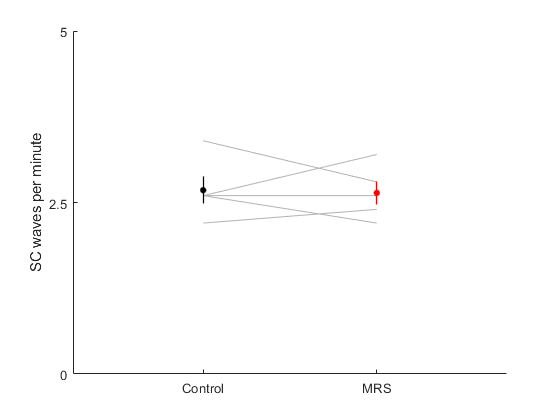

ylim([0 5]);
yticks([0:2.5:5]);

export_fig('.\EPS Panels\SCfrequency.eps');

Error using export_fig>parse_args (line 1102)
Folder .\EPS Panels does not exist!

Error in export_fig (line 279)
    [fig, options] = parse_args(nargout, fig, varargin{:});

compare2P(durs(:,1),durs(:,2),{'Control','MRS'},'Mean wave duration (s)',[.75 1.25],[10 15]);
ylim([0 40]);
yticks([0:20:40]);
export_fig('.\EPS Panels\SC_duration.eps');

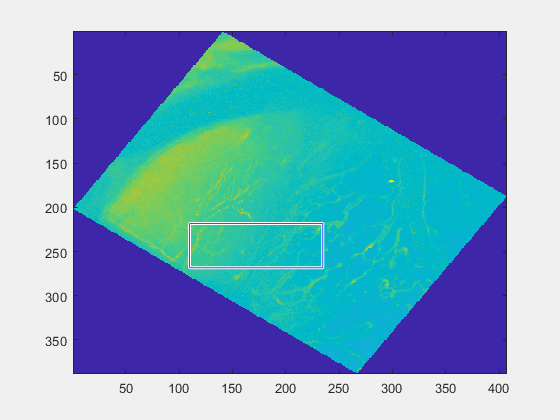

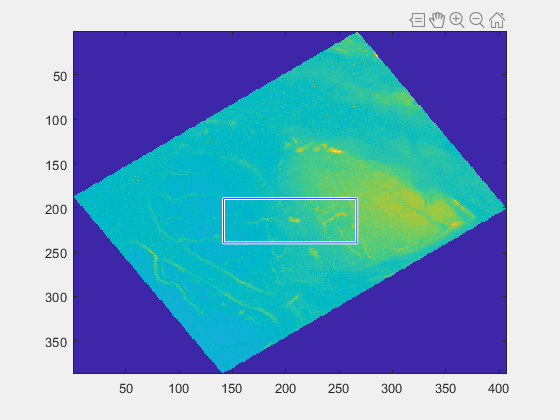

 [LICmov, RICmov] = ROIselection(dFoF);

 meanLIC = squeeze(mean(LICmov,1));
 percentLIC = prctile(meanLIC,30,2);
 meanRIC = squeeze(mean(RICmov,1));
 percentRIC = prctile(meanRIC,30,2);

% %%remove background transients from signal
top = dFoF(5:20,10:500,:); %picks area at top of image, middle to account for registration

Index in position 2 exceeds array bounds (must not exceed 488).

top = squeeze(mean(mean(top),2));
mid = dFoF(60:80,10:500,:);
mid = squeeze(mean(mean(mid),2));
diff = top - mid;
diff(diff < -0) = 0;
[pks,locs,w]=findpeaks(double(diff),'MinPeakHeight',0.02,'WidthReference','halfprom','MinPeakWidth',7,'Annotate','extents');
figure;
findpeaks(double(diff),'MinPeakHeight',0.02,'WidthReference','halfprom','MinPeakWidth',7,'Annotate','extents');



flash = zeros(size(top));
for i=1:size(w,1)
    ww = floor(w(i));
    wloc = locs(i);
    left = wloc-ww-2;
    right = wloc+ww+2;
    if left < 1
        left = 1;
    end
    if right > t
        right = t;
    end
    flash(left:right) = 1;
end

[m,n] = size(meanLIC(:,find(flash)));
percentLIC = repmat(percentLIC,1,n);
percentLIC = imnoise(percentLIC,'gaussian',0,.0001);
percentLIC = imgaussfilt(percentLIC);
meanLIC(:,find(flash)) = percentLIC;
[m,n] = size(meanRIC(:,find(flash)));
percentRIC = repmat(percentRIC,1,n);
percentRIC = imnoise(percentRIC,'gaussian',0,.0001);
percentRIC = imgaussfilt(percentRIC);
meanRIC(:,find(flash)) = percentRIC;
% 
smLIC = double(imgaussfilt(meanLIC,3));
smRIC = double(imgaussfilt(meanRIC,3));


%LIC & RIC
[peaksBinaryL] = getPeaks_dFoF(smLIC,0,0.02);
[peaksBinaryR] = getPeaks_dFoF(smRIC,1,0.02);

[peakStat, eventStats] = P2ry1_peakStats_dFoF(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
plotTimeSeries_dFoF(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat);
%%
savefile = 'ICmovs_peaks_dFoF_remflash.mat';
save([dname '\' foldername '\' savefile],'smLIC','smRIC','peaksBinaryR','peaksBinaryL'); 
